# Condiționarea rădăcinilor ecuațiilor algebrice

## Studiul condiționării

Să se studieze teoretic şi experimental condiţionarea problemei determinării rădăcinilor ecuaţiei polinomiale

$x^n+a_1x^{n-1}+a_2x^{n-2}+\cdots+a_n=0,$ (1)

cunoscându-se coeficienţii. Se va scrie o rutină pentru calculul numărului de condiţionare al fiecărei rădăcini şi se va studia grafic efectul perturbării fiecărui coeficient cu o variabilă aleatoare normală cu media 0 şi dispersia $10^{-10}$. Aplicaţie pentru ecuaţiile


$$(x-1)(x-2)\dots(x-n)=0$$


şi (1) pentru rădăcinile $x_k = 2^{-k}$. Se va lua ca exemplu practic pentru testare $n = 20$. Ce se întâmplă dacă perturbaţia urmează legea uniformă?

Vezi funcția `condpol`.

Verificare 

format long
n=20;
p=poly(1:n);
roots(p)

Să utilizăm funcția `condpol` la exemplul lui Wilkinson:

close all
format short g
xi=1:n;
nc=condpol(poly(xi),xi);
[ncs,i]=sort(nc');
disp([ncs,i])

          420            1
        43890            2
   2.0189e+06            3
   5.1483e+07            4
   8.2373e+08            5
   8.9237e+09            6
   6.8839e+10            7
    1.378e+11           20
   3.9156e+11            8
   1.3781e+12           19
   1.6816e+12            9
   5.5566e+12           10
   6.3797e+12           18
   1.4194e+13           11
   1.8121e+13           17
   2.8523e+13           12
   3.5438e+13           16
   4.4307e+13           13
   5.0243e+13           15
    5.401e+13           14



Vom studia acum influenţa unor perturbaţii mici normale şi respectiv uniforme asupra rădăcinilor polinomului lui Wilkinson.

Funcția `wilkinson` studiază efectul unor perturbații aleatoare normale asupra  polinomului lui Wilkinson $\prod_{k=1}^n(x-k)$. Perturbațiile au media 0 și dispersia $10^{-10}$.

Funcția `wilkinsonu` studiază efectul unor perturbații aleatoare cu distribuția uniformă pe intervalul $[0, 10^{-10}]$ asupra polinomului lui Wilkinson.

Studiul grafic al efectul perturbaţiilor asupra rădăcinilor polinomului lui Wilkinson.

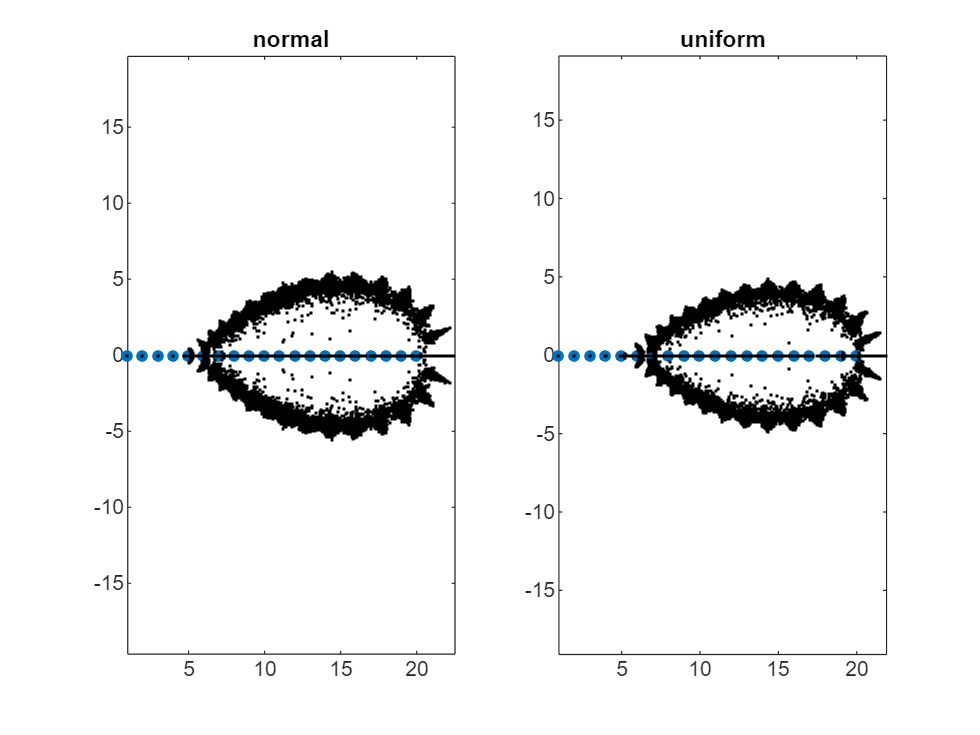

subplot(1,2,1)
wilkinson(20)
title('normal')
subplot(1,2,2)
wilkinsonu(20)
title('uniform')

## Funcții utilizate

### Funcția `condpol`

function nc=condpol(p,xi)
%CONDPOL conditionarea unei ecuatii polinomiale p(x)=0
%apel nc=condpol(p,xi)
%p - coeficienti
%xi - radacinile

if nargin<2
    xi=roots(p);
end
n=length(p)-1;
dp=(n:-1:1).*p(1:end-1); %derivata;
nc=1./(abs(xi.*polyval(dp,xi))).*(polyval(abs(p(2:end)),abs(xi)));
end

### Funcția `wilkinson`

Perturbație normală $\mu=0$ și $\sigma=10^{-10}$ pentru $\prod_{k=1}^{n}(x-k)$

function wilkinson(n)
%WILKINSON perturbatie normala pentru \_prod_{k=1}^{n}(x-k)

p=poly(1:n);
h=plot(1:n,zeros(1,n),'.');
set(h,'Markersize',15);
hold on
for k=1:1000
    r=randn(1,n+1);
    pr=p.*(1+1e-10*r);
    z=roots(pr);
    h2=plot(z,'k.');
    set(h2,'Markersize',4)
end
axis equal
end

### Funcția `wilkinsonu`

Perturbație uniformă $U\left[ 0, 10^{-10} \right]$pentru $\prod_{k=1}^{n}(x-k)$

function wilkinsonu(n)
p=poly(1:n);
h=plot(1:n,zeros(1,n),'.');
set(h,'Markersize',15);
hold on
for k=1:1000
    r=(1e-10)*rand(1,n+1);
    pr=p+r.*p; %.*(1+1e-10*r);
    z=roots(pr);
    h2=plot(z,'k.');
    set(h2,'Markersize',4)
end
axis equal
end